# **Introductory script contrasting wavefront-based to Gaussian PSF - based tree shrew optics**

*This script compares the wavefront-based tree shrew optics model to the Gaussian-PSF model*

**See also**: 

- `t_sceneForStimulusOnDisplay.mlx`

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2019*

# **Step 1.** Generate human WVF-based optics and plot the PSF/MTF at different wavelengths

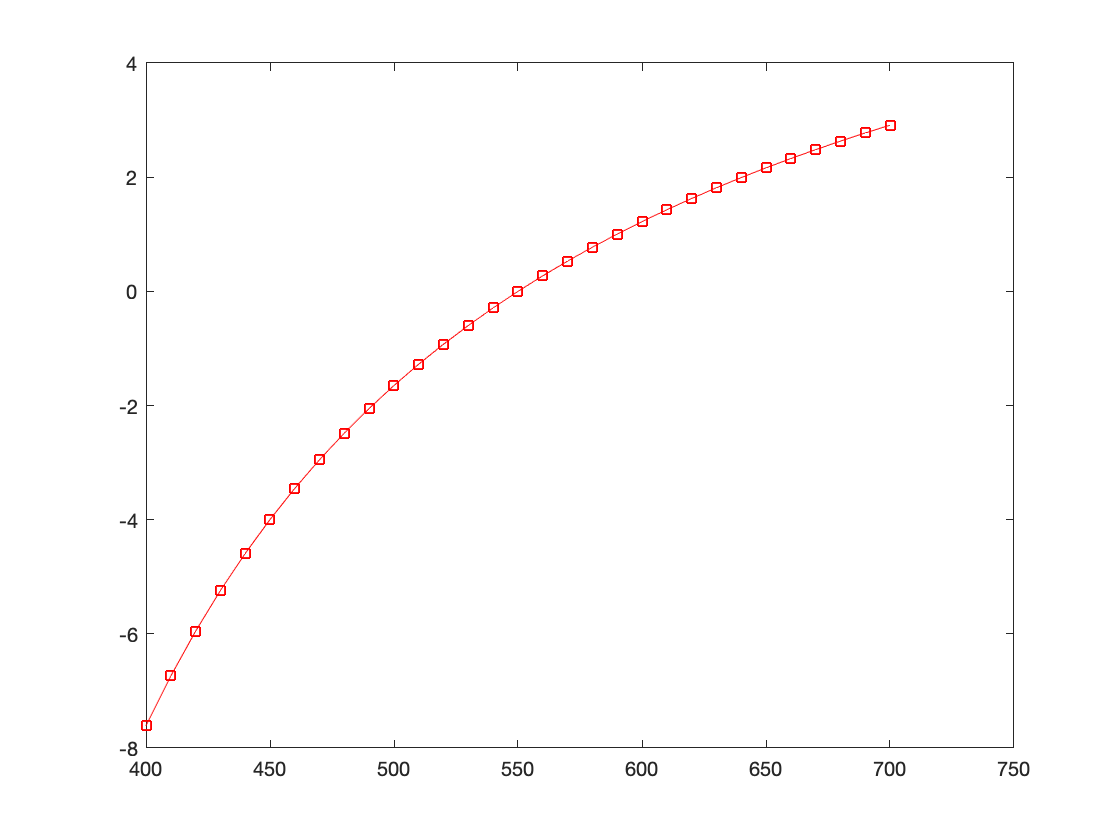

% Default tree shew optics
theDefaultOI = oiCreate('wvf human');

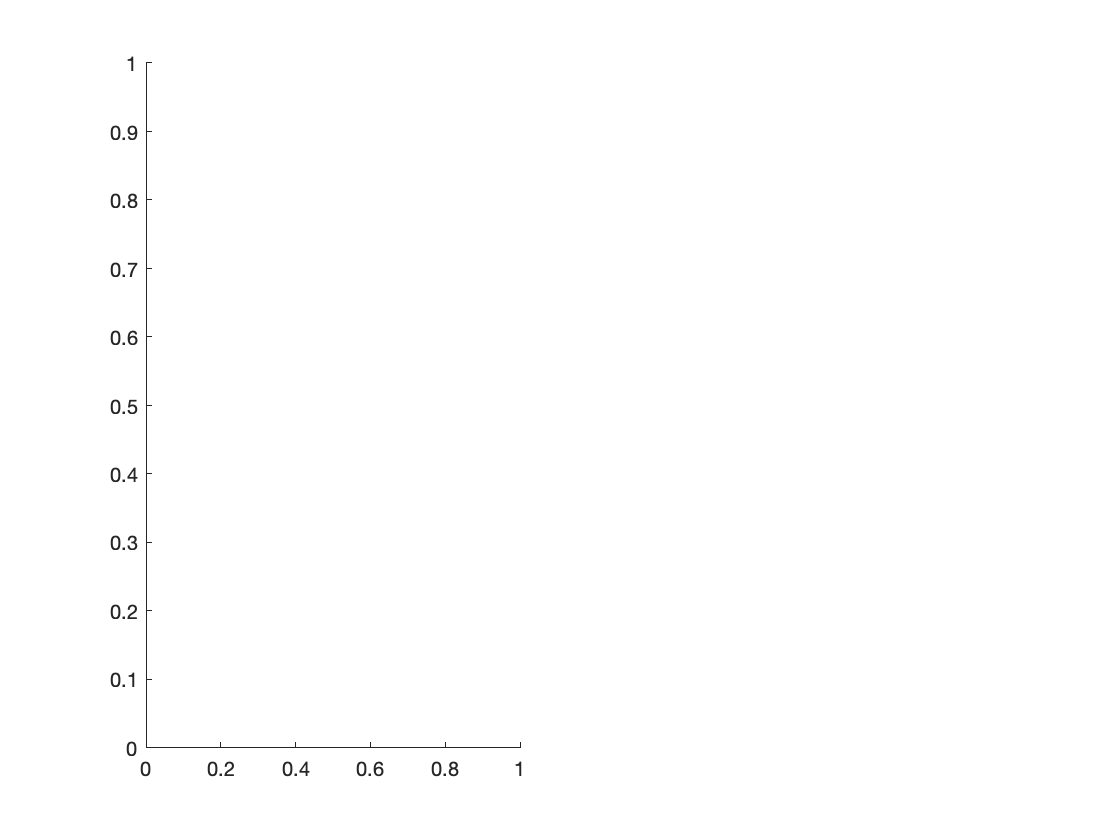

Error: File: visualizePSF.m Line: 106 Column: 43
Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

Error in visualizeOptics (line 14)
    visualizePSF(theOI, targetWavelength, spatialSupportArcMin, ...


visualizedSpatialSupportArcMin = 50;
visualizedSpatialSfrequencyCPD = 60.0;

visualizeOptics(theDefaultOI, 450, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD);


visualizeOptics(theDefaultOI, 500, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD);

visualizeOptics(theDefaultOI, 550, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD);

visualizeOptics(theDefaultOI, 600, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD);

visualizeOptics(theDefaultOI, 650, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD);


# **Step 2.** Generatewavefront-aberration based TreeShrew optics and plot the PSF/MTF at different wavelengths

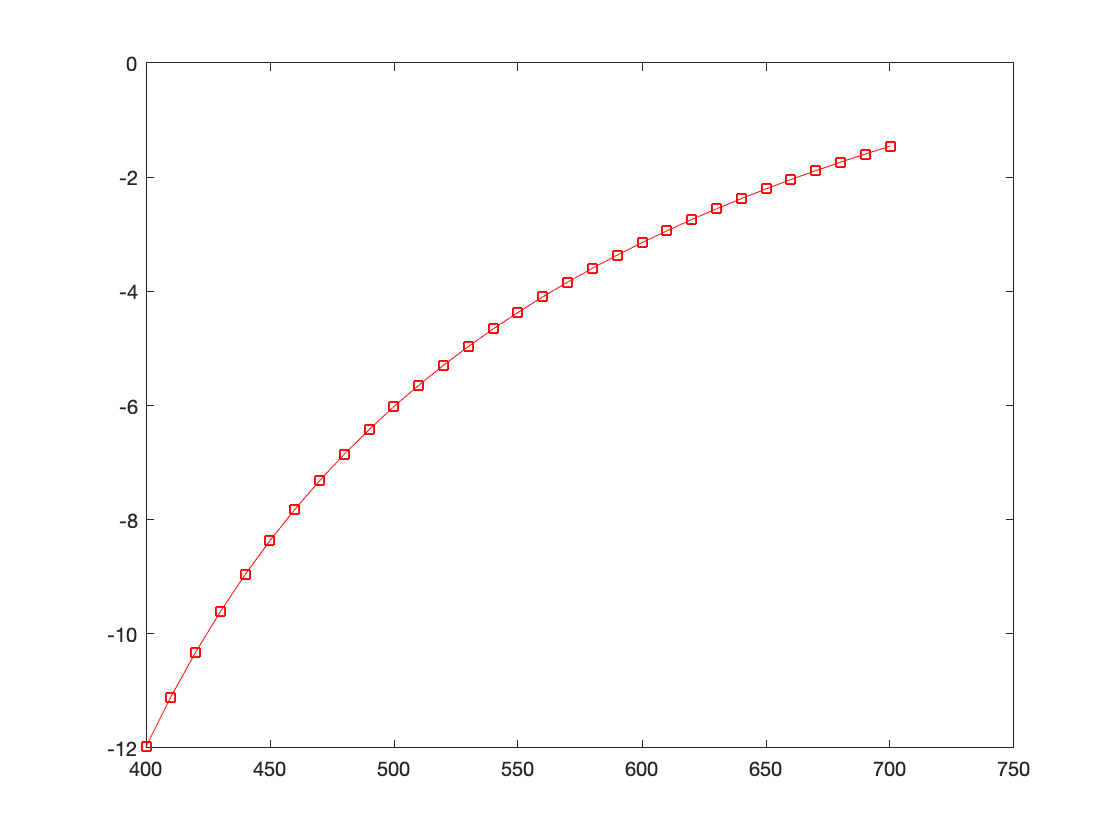

theWVFOI = oiTreeShrewCreate('opticsType', 'wvf', ...
    'name', 'wvf-based optics');

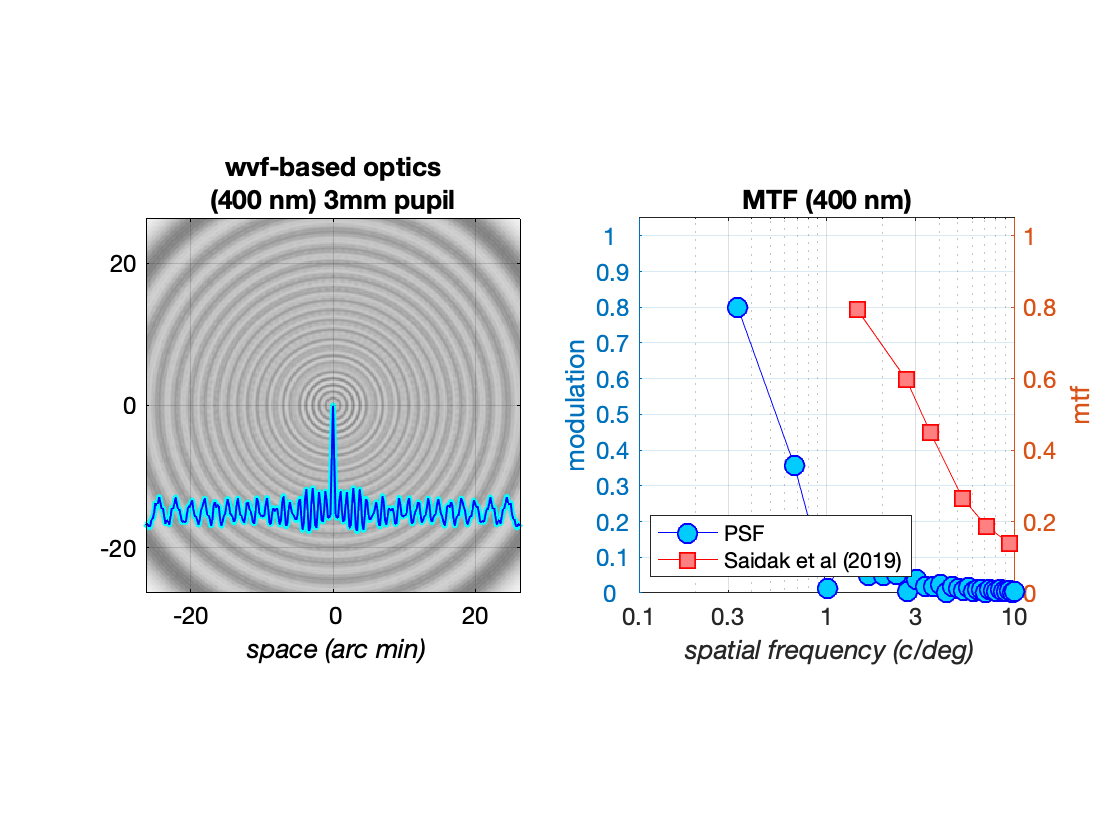

visualizedSpatialSupportArcMin = 50;
visualizedSpatialSfrequencyCPD = 10.0;
visualizeOptics(theWVFOI, 400, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData',  mtfTreeShrewFromPaper('SaidakEtAl_2019'));

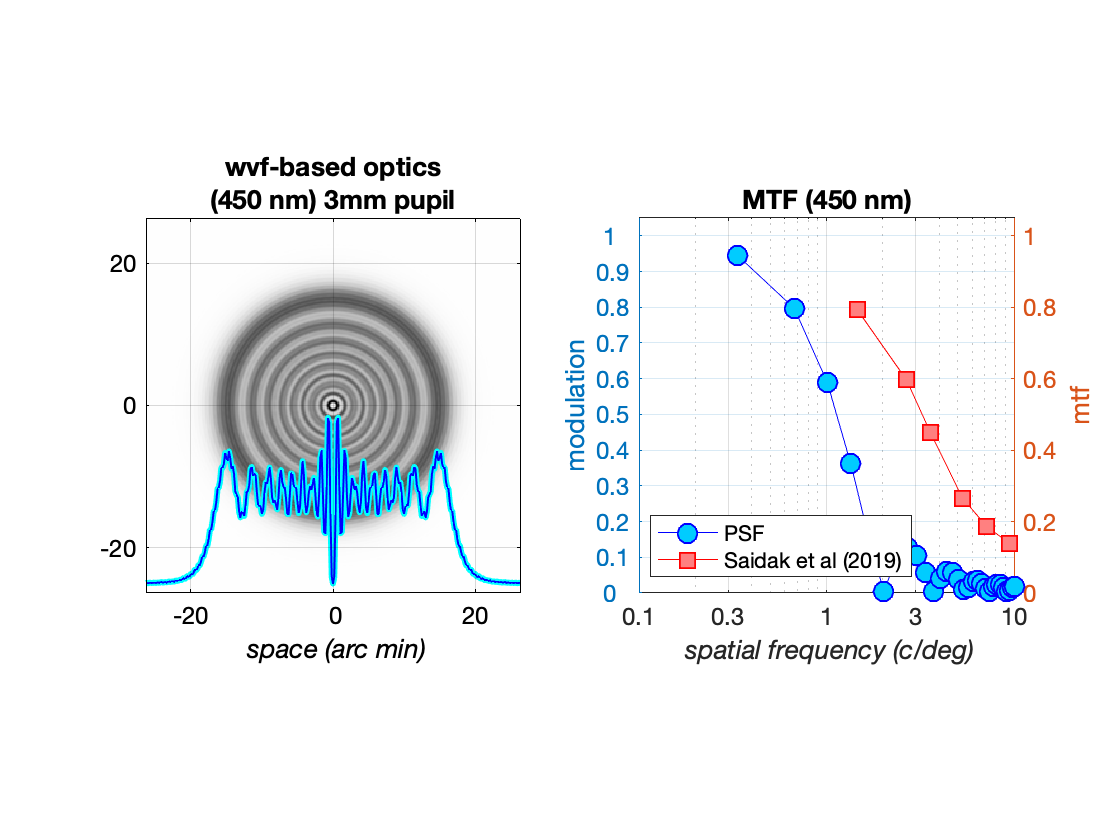


visualizeOptics(theWVFOI, 450, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData',  mtfTreeShrewFromPaper('SaidakEtAl_2019'));

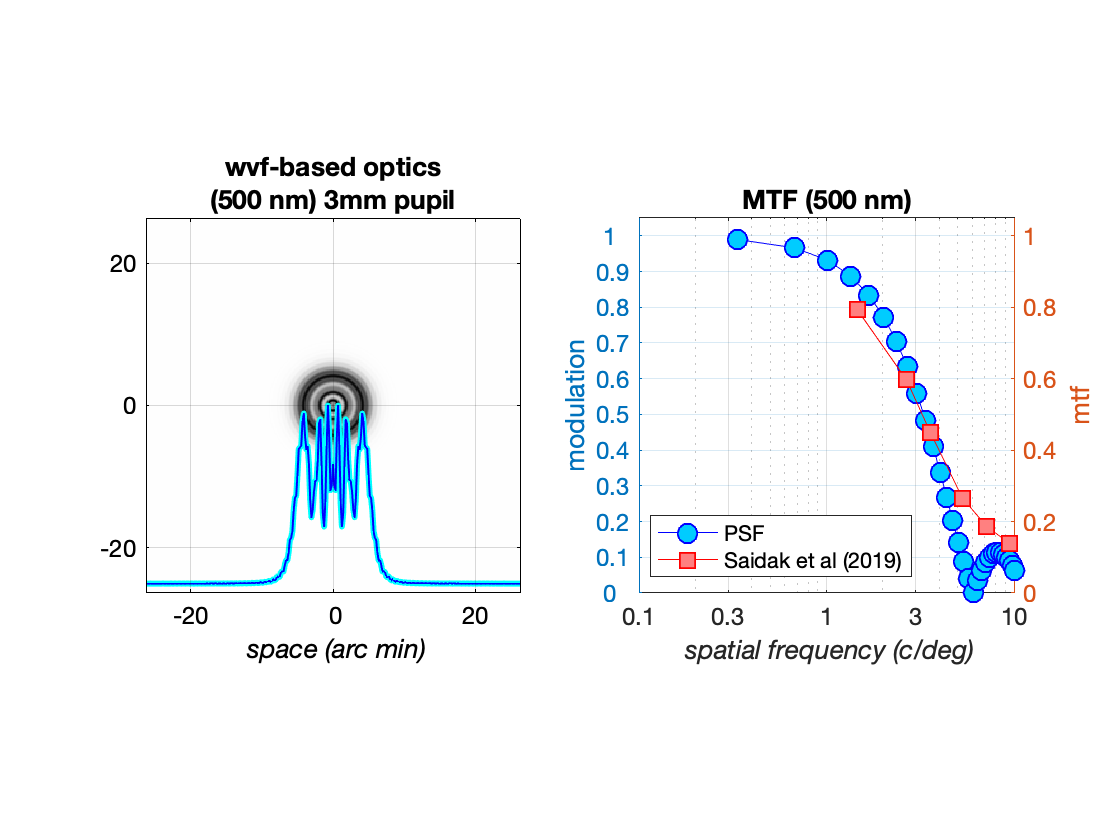


visualizeOptics(theWVFOI, 500, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData',  mtfTreeShrewFromPaper('SaidakEtAl_2019'));

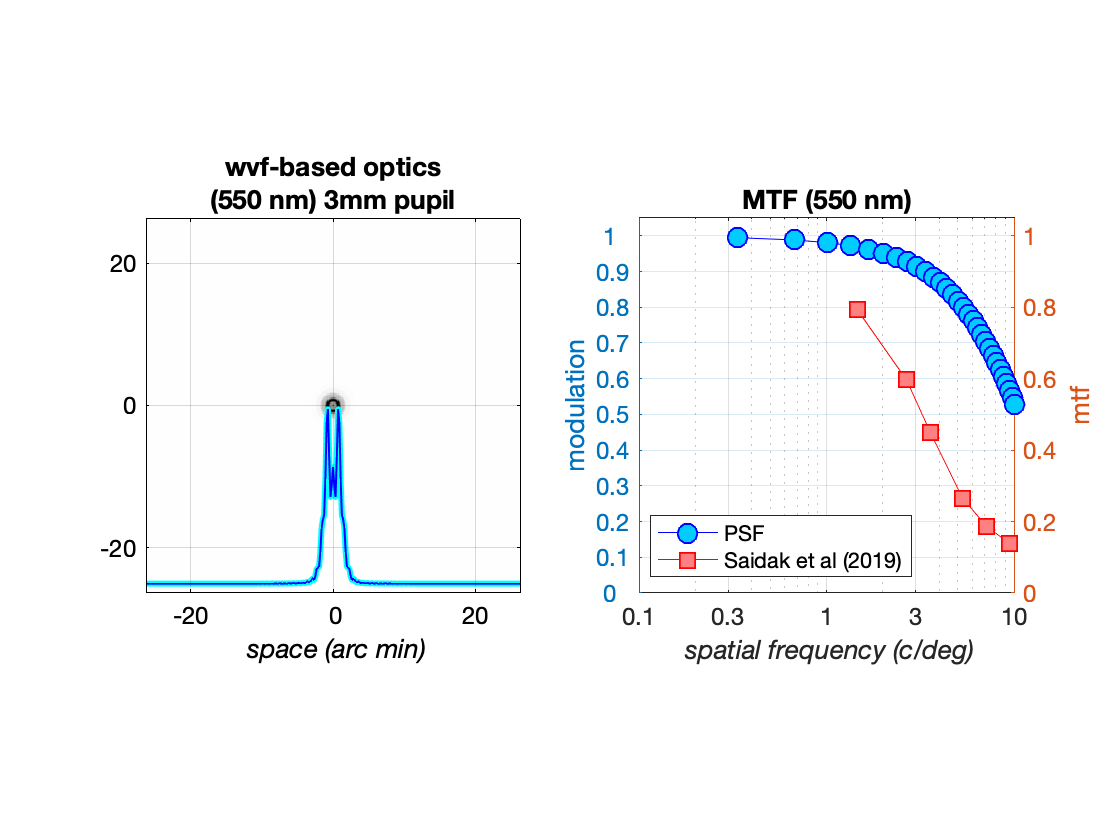


visualizeOptics(theWVFOI, 550, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData',  mtfTreeShrewFromPaper('SaidakEtAl_2019'));

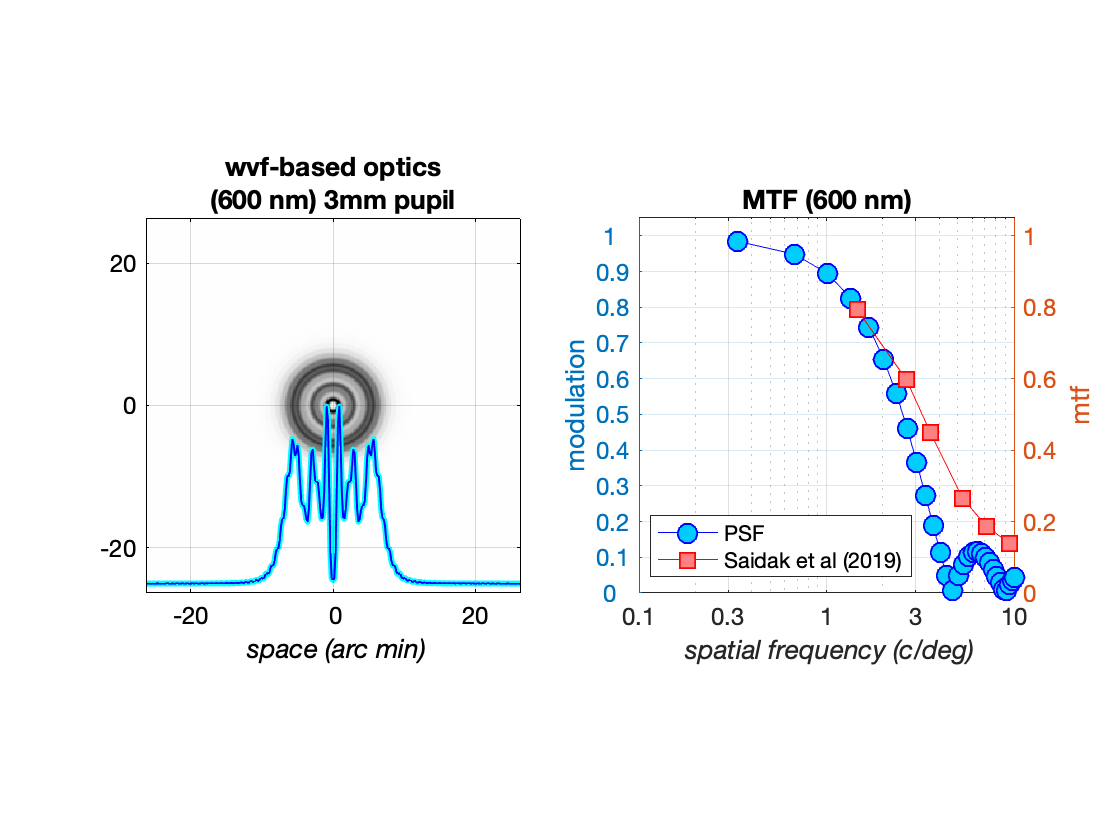


visualizeOptics(theWVFOI, 600, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData',  mtfTreeShrewFromPaper('SaidakEtAl_2019'));

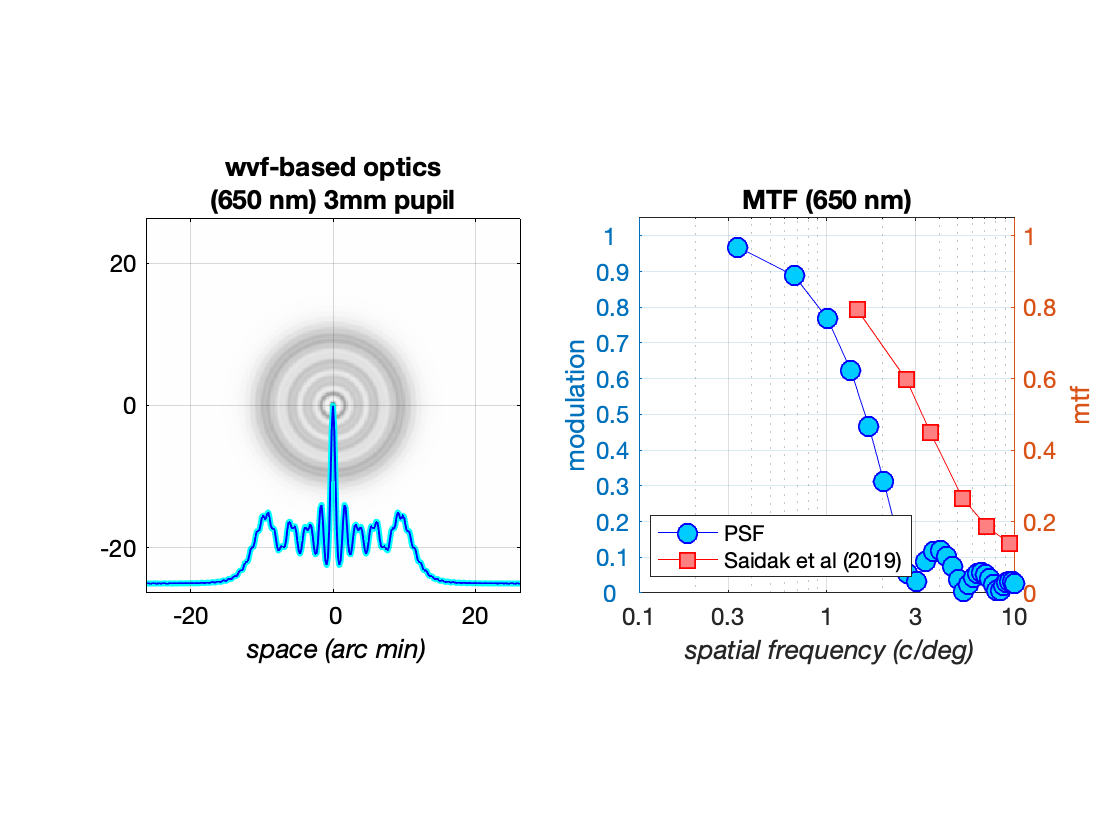


visualizeOptics(theWVFOI, 650, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData',  mtfTreeShrewFromPaper('SaidakEtAl_2019'));

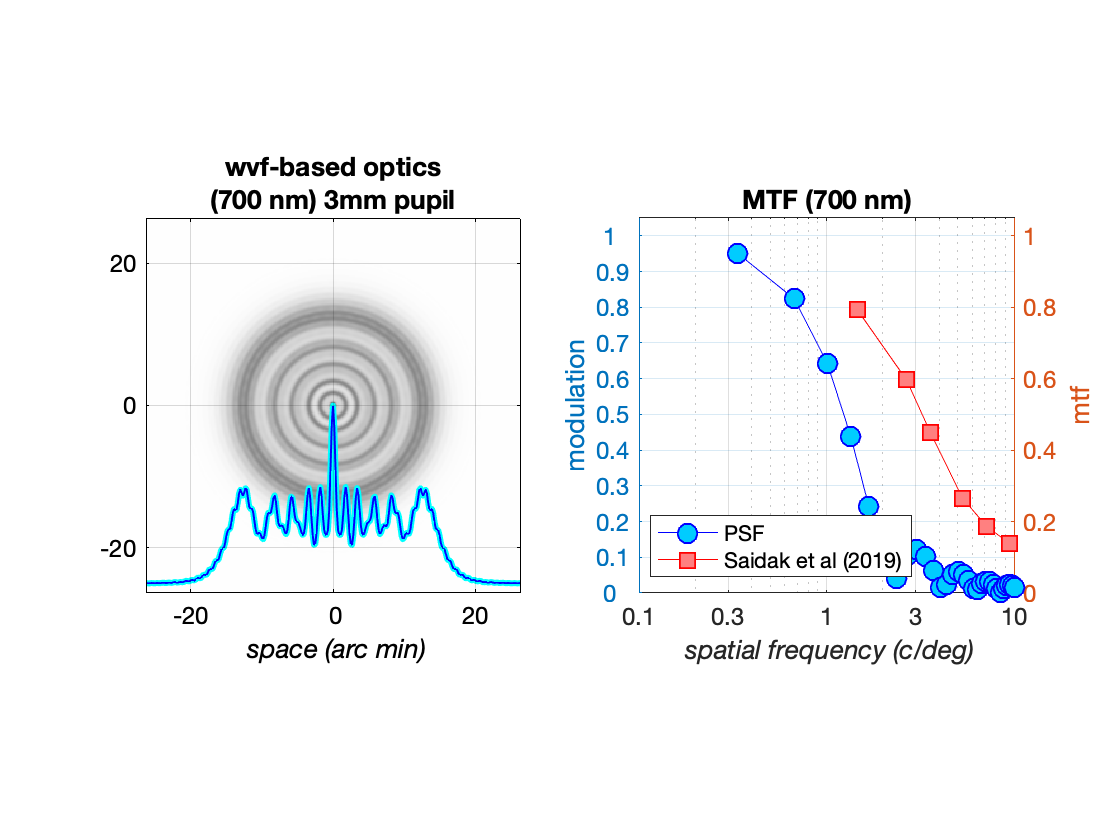

    
    visualizeOptics(theWVFOI, 700, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData',  mtfTreeShrewFromPaper('SaidakEtAl_2019'));